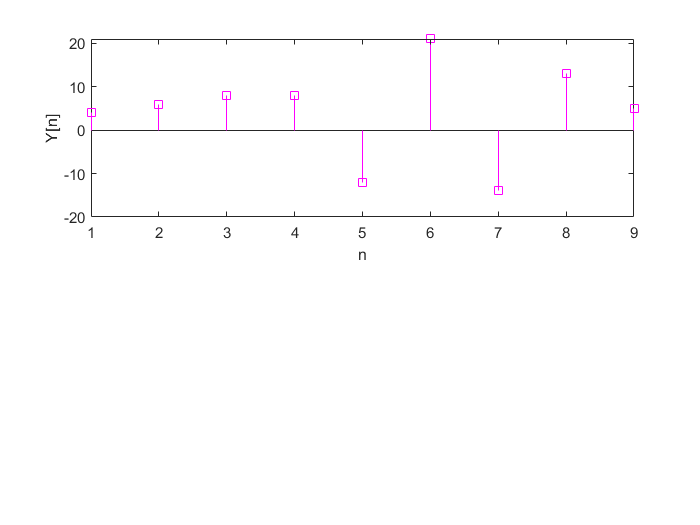

clc
close all
x=[2,-1,4,-7,5];
h=[2,4,2,4,1];
m=length(x);
n=length(h);
X=[x,zeros(1,n)];
H=[h,zeros(1,m)];
for i=1:m+n-1
    Y(i)=0;
    for j=1:m
        if(i-j+1>0)
            Y(i)=Y(i)+X(j)*H(i-j+1);
        else
        end
    end
end
figure;
title('Convolution of Two Signals without conv function');
subplot(2,1,1);stem(Y,'-ms');xlabel('n');ylabel('Y[n]');